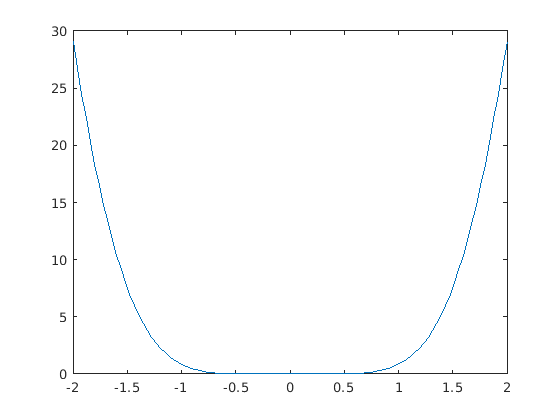

x = 2;
f = @(x) sin(x).*x.^5;

df = derivative(f);
eror = [0.0001:0.0002:0.1];
u = @(x) f(x)/df(x);
h = @(x) x-f(x)/df(x);
%plot(eror,f(eror),eror,zeros(1,length(eror)))
%hold on
x1 = Inf;
A = [];
B = [];
C = [];
D = [];
xx = linspace(-2,2,100);
for i = eror
    %I
    [x1, it] = newton_method(f,x,i,1);
    A = [A,it];

    %II
    [x1, it] = newton_method(f,x,i,6);
    B = [B,it];
    
    %III
    [x1, it] = newton_method(u,x,i,1);
    C = [C,it];

    %IV
    [x1, it] = steffenson(h,x,i);
    D = [D,it];
end

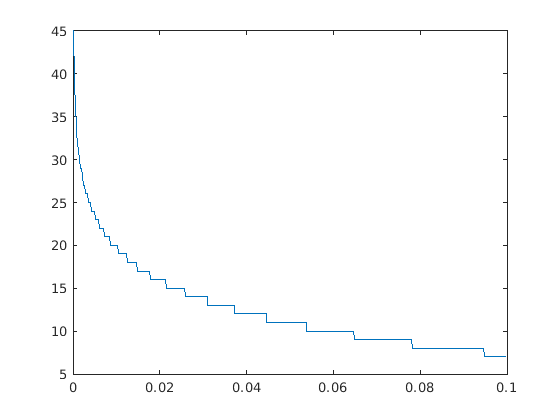

plot(eror,A)

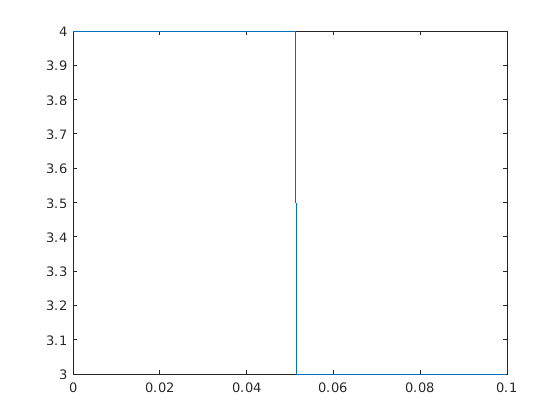


plot(eror,B)

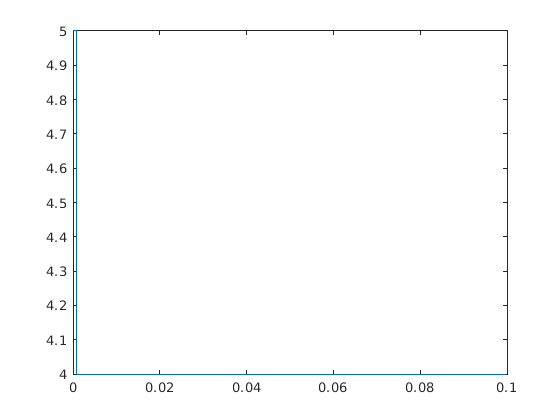


plot(eror,C)

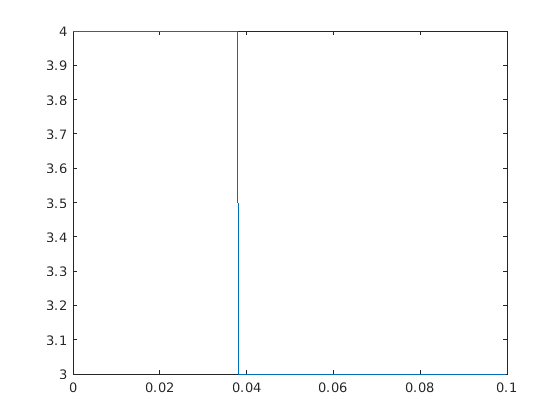


plot(eror,D)

function [df] = derivative(f)
%[df] = derivative(f)
%   f anonymous function
df=matlabFunction(diff(sym(f)));
end

function [x,num] = newton_method(f,x,error,M)
%Newton method
x_prev=Inf;
df=derivative(f);
num=0;
while abs(x-x_prev)>error
    x_prev=x;
    x=x-M*f(x)/df(x);
    num=num+1;
end
end

function [x,num] = steffenson(g,x0,error)
% Steffenson method
x=Inf;
xnew=x0;
num=0;
while (abs(xnew-x)>error)
    x=xnew;
    y=g(x);
    z=g(y);
    xnew=x-(y-x)^2/(z-2*y+x);
    num=num+1;
end
x=xnew;
end



